Since 20220727, I have been doing simulation of FLP with modified version (like change the population of 256 channels to 512 channels, detailed changes see the script /Users/mapingchuan/Desktop/ChenLab_Data/MATLAB analysis/FLP_simulation_20220727.mlx). And for the results of the threshold of photon counts, I've seen very different results. To figure out why it's the case, I need to just change one thing at a time to figure out why it's causing all these difference. This time I'm using the same tau1 and tau2, same autofluorescence, DC, and afterpulse for the simulation, basically repeat the simulation of /Users/mapingchuan/Desktop/ChenLab_Data/MATLAB analysis/FLP_simulation_20220326.mlx with just different tau1 and tau2.

% give this simulation a name
SimulationName='simulation_ACh_20220806_2';
savefolder='/Users/mapingchuan/Desktop/ChenLab_Data/';

% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/mapingchuan/Desktop/ChenLab_Data/simulation_ACh_20220806_2/'

cd(filepath)

% guassian fitting curve, used what's from before
width=0.1554;
miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
figure
plot(x,Gaussian_y)

Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
plot(x,Gaussian_y)


Gaussian_y=Gaussian_y';


cumulative_prf=cumsum(Gaussian_y);
figure
plot(cumulative_prf)


PrfName='prf_gaussian.mat';
save(PrfName,'Gaussian_y')

p1_samples=0.6:0.02:1.0; % simulate the p1 range from 0.6 to 1.0
AF=20000;
tau1=2.8607; % 
tau2=0.6874;
DC=0;
afterpulse_ratio=0.01;

SS_samples=20000:20000:500000; % simulated sample size range from 20000 to 500000.


% This is the content of the script for batch processing.
% for i=1:21
    rng('shuffle','twister')
    p1=p1_samples(i);
    p2=1-p1;
    PopulationName=[SimulationName,'_FLP_population_',num2str(p1),'.mat'];
    GenPop512_FLP(100000, p1, p2, tau1, tau2, PopulationName); 
    for j=1:25
        SS=SS_samples(j);
        afterpulse=round(afterpulse_ratio*SS);
        mkdir([num2str(SS),'_',num2str(p1)])
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            FLIMsim512_FLP(SS,DC,afterpulse,PrfName, PopulationName,samplename)
        end
    end
% end


c=parcluster()

for i=1:21

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-iMac
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/mapingchuan/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2021b
   RequiresOnlineLicensing: false

    

    batch('FLP_simulation_batch')
end

ans = 

 Job

    Properties: 

                   ID: 22
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 09-Aug-2022 11:33:52
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

% give this simulation a name
SimulationName='simulation_ACh_20220804_2'; % without DC and afterpulse
savefolder='/Users/mapingchuan/Desktop/ChenLab_Data/';

% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/mapingchuan/Desktop/ChenLab_Data/simulation_ACh_20220804_2/'

cd(filepath)

p1_samples=0.6:0.02:1.0; % simulate the p1 range from 0.6 to 1.0
AF=20000;
tau1=2.706; % tau1 and tau2 from simulation 20220326
tau2=0.2613;
DC=0;
afterpulse=0;

SS_samples=20000:20000:500000; % simulated sample size range from 20000 to 500000.

c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-iMac
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/mapingchuan/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2021b
   RequiresOnlineLicensing: false

    

for i=1:21
    batch('FLP_simulation_batch')
end

ans = 

 Job

    Properties: 

                   ID: 43
                 Type: independent
             Username: mapingchuan
                State: running
       SubmitDateTime: 05-Aug-2022 00:53:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

tau3=2.4922;
p3=0.2700;
tau4=0.4069;
p4=0.7300;
PopulationName='Simulation_20220805_autofluo_population';

GenPop512_FLP(100000, p3, p4, tau3, tau4, PopulationName);

AF=20000;
SS_all=zeros(1,50);
DC=0;
afterpulse=0;
PrfName='prf_gaussian.mat';


mkdir([num2str(AF),'_AF'])

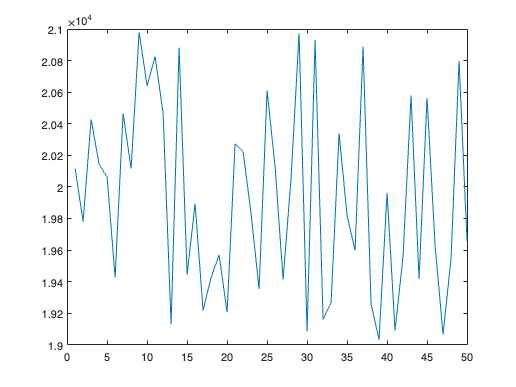

for i=1:50
    SS=randi(2000)+19000; % 10% of fluctuation
    SS_all(i)=SS;
    samplename=[num2str(AF),'_AF/',num2str(i),'_auto.mat'];
    FLIMsim512_FLP(SS,DC,afterpulse,PrfName, PopulationName,samplename)
end

figure
plot(SS_all)

p1_samples=0.6:0.02:1.0; % simulate the p1 range from 0.6 to 1.0
AF=20000;
tau1=2.706; % tau1 and tau2 from simulation 20220326
tau2=0.2613;
DC=1500;
afterpulse_ratio=0.01;

SS_samples=20000:20000:500000; % simulated sample size range from 20000 to 500000.

c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-mbp
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

for i=1:21
    batch('DC_afterpulse_simulation_batch')
end

ans = 

 Job

    Properties: 

                   ID: 39
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 08-Aug-2022 12:17:36
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

p1_samples=0.6:0.02:1.0; % simulate the p1 range from 0.6 to 1.0
AF=20000;
tau1=2.706; % tau1 and tau2 from simulation 20220326
tau2=0.2613;
DC=1500;
afterpulse_ratio=0.01;

SS_samples=20000:20000:500000; % simulated sample size range from 20000 to 500000.

c=parcluster()

for i=1:21
    batch('DC_afterpulse_simulation_batch')
end

cd(filepath)

ch=1;
for i=1:21
    p1=p1_samples(i);
 

    for j=1:25
        SS=SS_samples(j);
%         mkdir([num2str(SS),'_',num2str(p1),'_auto'])
        
        tau_avg=[];
        tau_avgTrunc=[];
        tau_empTrunc=[];
        photoncount=[];
        p1_sim=[];
        chi2=[];
        beta2=[];
        beta4=[];
        beta5=[];
        beta6=[];
        lifetime_histograms=[];
        
        peak_afterC=[];
        peak_withauto=[];
        
        for k=1:50
            
            
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n';
            spc.lifetimes{1}=n_ACh+autofluorescence_FLP';
            
            
            spc_fitexp2gaussGY(ch);
%             spc_adjustTauOffset(1);
            
            
            photoncount(k)=sum(spc.lifetimes{1});
            p1_sim(k)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3);
            tau_avg(k)=spc.fits{ch}.avgTau; % mean Tau calculated from fit
            tau_avgTrunc(k)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k)=spc.fits{ch}.EmpTauTrunc;
            chi2(k)=spc.fits{ch}.redchisq;
            beta2(k)=spc.fits{ch}.beta2;
            beta4(k)=spc.fits{ch}.beta4;
            beta5(k)=spc.fits{ch}.beta5;
            beta6(k)=spc.fits{ch}.beta6;
            lifetime_histograms=[lifetime_histograms spc.lifetimes{1}];
            
            peak_afterC(k)=mean(find(n==max(n)));
            peak_withauto(k)=mean(find(spc.lifetimes{1}==max(spc.lifetimes{1})));
            
        end
        
        photoncount=transpose(photoncount);
        tau_avg=transpose(tau_avg);
        tau_avgTrunc=transpose(tau_avgTrunc);
        tau_empTrunc=transpose(tau_empTrunc);
        p1_sim=transpose(p1_sim);
        chi2=transpose(chi2);
        beta2=transpose(beta2);
        beta4=transpose(beta4);
        beta5=transpose(beta5);
        beta6=transpose(beta6);
        
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        save(result_name,'photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1_sim','chi2','beta2','beta4','beta5','beta6','lifetime_histograms')
    end
end

